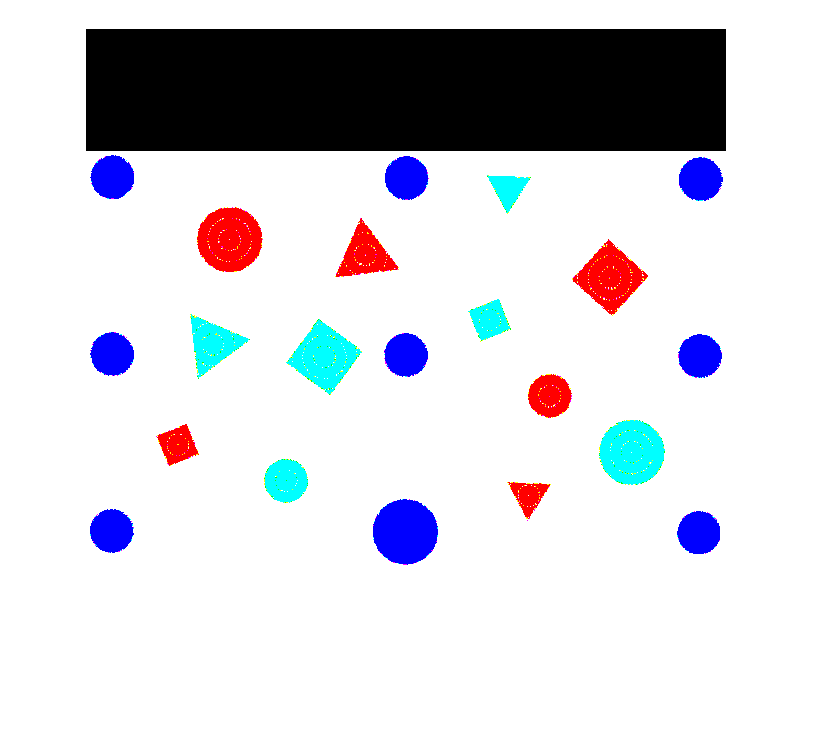

% sim = coppeliaRobot();

init_image = imread("init_image3.jpg");
dest_image = imread("init_image1.jpg");
% ---

% a = EGB339_21S2_19(sim, init_image, dest_image)
% init_xy=a{1}
% dest_xy=a{2}

init_image = double(init_image);
dest_image = double(dest_image);

q = [0 -24 -21 45 0]; % Perfect for top view picture
q0 = [0 0 0 0 0];
setJointPositions(sim, q);
pause(5)

% Capture image
% Turn to DOUBLE
image = double(getImage(sim));
image(1:122,:,:) = 0;
imshow(image)



% data = extractData_(image, 1600);
% initData = extractData_(init_image, 37260);
% destData = extractData_(dest_image, 37260);

## Test extractData

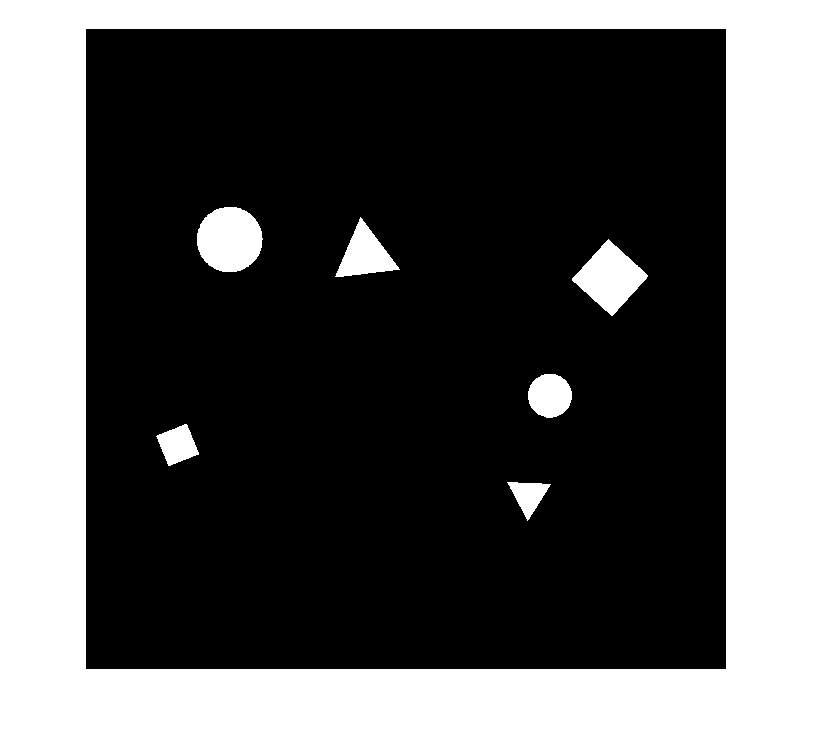

    sizeThreshold = 1600;
    r = image(:,:,1);
    g = image(:,:,2);
    b = image(:,:,3);

    red = imclose(r./(r+g+b) > 0.5, ones(5,5));
    blue = imclose(b./(r+g+b) > 0.5, ones(5,5));
    green = imclose(g./(r+g+b) > 0.5, ones(5,5));

    imshow(red)

    % Get Shape props from colour plain
    if sum(sum(red))>0
        redProps = regionprops("struct",red,"Centroid","Area","Circularity");
    else
        redProps = 0;
    end

redPropsClone = 6×1 struct array with fields:
    Area
    Centroid
    Circularity



    % % if sum(sum(blue))>0
    % %     blueStats = regionprops("table",blue,"Centroid","Area","Circularity");
    % % else
    % %     blueStats = 0;
    % % end
    if sum(sum(green))>0
        greenProps = regionprops("struct",green,"Centroid","Area","Circularity");
    else
        greenProps = 0;
    end

%     redData = processData(redProps, "red", 1600)
    % Get red shapes full data
    [rowNum,~] = size(redProps);
    for i = 1:rowNum
        % remove possible noise
        if redProps(i).Area <= 30
            continue
        end
        % Set shape colour
        redData(i,1) = "red";
        % determine shape
        if redProps(i).Circularity > 0.85
            redData(i,2)= "Circle";
        elseif redProps(i).Circularity <= 0.85 && redProps(i).Circularity > 0.7
            redData(i,2)= "Square";
        elseif redProps(i).Circularity <= 0.70
            redData(i,2)= "Triangle";
        end
        %determine size
        if redProps(i).Area > sizeThreshold
            redData(i,6)= "True";
        else
            redData(i,6)= "False";
        end
        %get centroid and area
        redData(i,3)= redProps(i).Centroid(1);
        redData(i,4)= redProps(i).Centroid(2);
        redData(i,5)= redProps(i).Area;
    end
    redData

redData = 6×6 string array
    "red"    "Square"      "92.2"        "416.4676"    "1095"    "False"
    "red"    "Circle"      "144.1872"    "211.058"     "3382"    "True" 
    "red"    "Triangle"    "279.6755"    "226.154"     "1889"    "True" 
    "red"    "Triangle"    "443.2035"    "467.2518"    "850"     "False"
    "red"    "Circle"      "464.4489"    "367.2248"    "1517"    "False"
    "red"    "Square"      "524.6419"    "249.2758"    "3013"    "True" 



    % Get green shapes full data

    [rowNum,~] = size(greenProps);
    for k = 1:rowNum
        %remove possible noise
        if greenProps(k).Area<=30
            continue
        end
        %get shape colour
        greenData(k,1)="green";
        %determine shape
        if greenProps(k).Circularity > 0.85
            greenData(k,2)= "Circle";
        elseif greenProps(k).Circularity <=0.85 && greenProps(k).Circularity > 0.7
            greenData(k,2)= "Square";
        elseif greenProps(k).Circularity <= 0.70
            greenData(k,2)= "Triangle";
        end
        %determine size
        if greenProps(k).Area > sizeThreshold
            greenData(k,6)= "True";
        else
            greenData(k,6)= "False";
        end
        %get centroid and area
        greenData(k,3)= greenProps(k).Centroid(1);
        greenData(k,4)= greenProps(k).Centroid(2);
        greenData(k,5)= greenProps(k).Area;
    end

Intermediate dot '.' indexing produced a comma-separated list with 6 values, but it must produce a single value to perform subsequent indexing operations.

Related documentation


    % % % Get blue shapes full data
    % % [rowNum,~] = size(blueProps);
    % % for i = 1:rowNum
    % %     % remove possible noise
    % %     if blueProps.Area(i,1)<=30
    % %         continue
    % %     end
    % %     % get shape colour
    % %     blueData(i,1)="blue";
    % %     % determine shape
    % %     if arrayIn.Circularity(i,:)>0.85
    % %         blueData(i,2)= "Circle";
    % %     elseif arrayIn.Circularity(i,:)<=0.85 && arrayIn.Circularity(i,:)>0.7
    % %         blueData(i,2)= "Square";
    % %     elseif arrayIn.Circularity(i,:)<=0.70
    % %         blueData(i,2)= "Triangle";
    % %     end
    % %     % determine size
    % %     if arrayIn.Area(i,1) > sizeThreshold
    % %         blueData(i,6)= "True";
    % %     else
    % %         blueData(i,6)= "False";
    % %     end
    % %     % get centroid and area
    % %     blueData(i,3)= arrayIn.Centroid(i,1);
    % %     blueData(i,4)= arrayIn.Centroid(i,2);
    % %     blueData(i,5)= arrayIn.Area(i,1);
    % % end

    data = cat(1, redData, greenData);






init_xy_image = zeros(2,3);
for i=1:3
    temp1 = [data(:,1)==initData(i,1) data(:,2)==initData(i,2) data(:,6)==initData(i,6)];
    temp2 = temp1(:,1) + temp1(:,2) + temp1(:,3);
    postition = find(temp2==3);
    init_xy_image(1,i) = str2num(data(postition, 3));
    init_xy_image(2,i) = str2num(data(postition, 4));
end
% init_xy_image

dest_xy_image = zeros(2,3);
for i=1:3
    temp1 = [data(:,1)==destData(i,1) data(:,2)==destData(i,2) data(:,6)==destData(i,6)];
    temp2 = temp1(:,1) + temp1(:,2) + temp1(:,3);
    postition = find(temp2==3);
    dest_xy_image(1,i) = str2num(data(postition, 3));
    dest_xy_image(2,i) = str2num(data(postition, 4));
end
% dest_xy_image



%% HOMOGRAPHY
% Get colour plains
red = image(:,:,1);
green = image(:,:,2);
blue = image(:,:,3);

% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));

% Get blue shapes' stats
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles);
hold on;
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*");
hold off;

% Store data
blueCentroids = cat(1,blueStats.Centroid);
blueAreas = cat(1,blueStats.Area);

% Left bottom circle = start circle
startCircleCentroid = [min(blueCentroids(:,1))+10 max(blueCentroids(:,2))-10];

i = [blueCentroids(:,1) < startCircleCentroid(1),  blueCentroids(:,2) > startCircleCentroid(2)];
i = i(:,1)+i(:,2);
startPosition = find(i==2);

% Clone variable
centroidsNew = blueCentroids;
% Remove the largest circle
centroidsNew(startPosition,:) = [];
% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-blueCentroids(startPosition,1)).^2 + abs(centroidsNew(:,2)-blueCentroids(startPosition,2)).^2)];
% 4th column: Add sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)];
% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);
% Now put them in P, order is right as required
P = [blueCentroids(startPosition,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ];
% The Euclidean workspace coordinates of the markers
Q = [ 20 182.5 182.5 20 345 345 345 182.5 20;  560 560 290 290 560 290 20 20 20;  ones(1,9) ];
H = simple_homography(P,Q);


%% CALUCULATE COORDINATES
% Realworld initial coordinates
init_xy = zeros(2,3);
init_xy_image = [init_xy_image;  ones(1,3)];

temp_xy = H * init_xy_image(:,1);
init_xy(:,1) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * init_xy_image(:,2);
init_xy(:,2) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * init_xy_image(:,3);
init_xy(:,3) = temp_xy(1:2,:)./temp_xy(3,:);

% Realworld destination coordinates
dest_xy = zeros(2,3);
dest_xy_image = [dest_xy_image;  ones(1,3)];

temp_xy = H * dest_xy_image(:,1);
dest_xy(:,1) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * dest_xy_image(:,2);
dest_xy(:,2) = temp_xy(1:2,:)./temp_xy(3,:);

temp_xy = H * dest_xy_image(:,3);
dest_xy(:,3) = temp_xy(1:2,:)./temp_xy(3,:);


% % init_xy = ?? % must be 3x2 matrix 
% determine the destination position of each cylinder. This must be a
% 3 x 2 matrix, with one row per shape, each row is (x,y) position of
% a cylinder 
% % dest_xy = ?? % must be 3x2 matrix 

retval = {init_xy, dest_xy};


%% REMOVE BEFORE SUBMIT
cylinderPos = [init_xy(1,1) init_xy(2,1); init_xy(1,2) init_xy(2,2); init_xy(1,3) init_xy(2,3)]
setCylinderPosition(sim, cylinderPos);
% 
% 
% 
% 


%% MOVE THE CYLINDERS FROM INITIAL TO DESTINATION POSITIONS 

for i = 1:3
    % Reach to initial position
    reach_(sim, init_xy(1,i), init_xy(2,i), 150);
    pause(2);
    reach_(sim, init_xy(1,i), init_xy(2,i), 50);
    pause(2);
    setSuctionCup(sim, 1);
    reach_(sim, init_xy(1,i), init_xy(2,i), 150);
    pause(2);
    
    % Reach to destination position
    reach_(sim, dest_xy(1,i), dest_xy(2,i),150);
    pause(2);
    reach_(sim, dest_xy(1,i), dest_xy(2,i),50);
    pause(2);
    setSuctionCup(sim, 0);
    reach_(sim, dest_xy(1,i), dest_xy(2,i),150);
    pause(2);
     
%     % Back to origin
%     q_current = getJointPositions(sim);
%     q_mid = jtraj(q_current, q0, 2);
%     for q=q_mid'
%         setJointPositions(sim, q);
%     end
end
